# Helmholtz Coil

Ref: [Wikipedia](https://en.wikipedia.org/wiki/Helmholtz_coil)

## Formula

A Helmholtz pair consists of two identical circular magnetic coils, separated by `h`, which equals to the coil radius `R` (i.e., `h=R`).

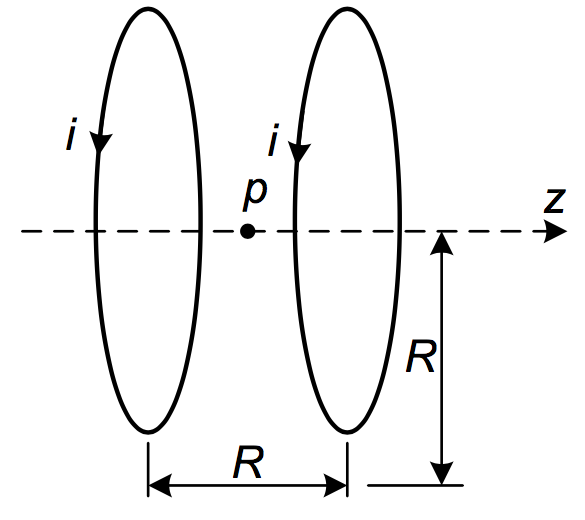

The magnetic field along the axis is


$$B\left(z\right)=\frac{1}{2}\mu_0 \text{ }N\text{ }R^2 I\left\lbrace {\left\lbrack R^2 +\left(z+\frac{R}{2}\right)\right\rbrack }^{−\frac{3}{2}} +{\left\lbrack R^2 +\left(z−\frac{R}{2}\right)\right\rbrack }^{−\frac{3}{2}} \right\rbrace \ldotp$$


At `z=0`, the field is simplfied as


$$B\left(0\right)={\left(\frac{4}{5}\right)}^{\frac{3}{2}} \text{ }\frac{\mu_0 \text{ }N\text{ }I}{R}\ldotp$$


The field expression of a single coil at an arbitary position is (Ref: [physicspages](http://www.physicspages.com/2013/04/18/magnetic-field-of-current-loop-off-axis-field/))


$$B\left(\mathbf{r}\right)=\frac{\mu_0 I\text{ }R}{4\pi }\int_0^{2\pi } d\varphi \frac{z\text{ }sin\varphi \text{ }\hat{\mathbf{r}} +\left(R−r\text{ }sin\varphi \text{ }\right)\hat{\mathbf{z}} }{{\left(R^2 +r^2 +z^2 −2\text{ }r\text{ }R\text{ }sin\varphi \text{ }\right)}^{3/2} }\ldotp$$


With the following formulas, the field above can be numerically calculated


$$\int_0^{2\pi \text{ }} \frac{sin\varphi \text{ }}{{\left(a−sin\varphi \text{ }\right)}^{3/2} }d\varphi =\frac{2}{\sqrt{a−1}\left(a+1\right)}\left\lbrack a\text{ }E\left(x_a \right)−\left(a+1\right)F\left(x_a \right)\right\rbrack ,$$


and 


$$\int_0^{2\pi \text{ }} \frac{1}{{\left(a−sin\varphi \text{ }\right)}^{3/2} }d\varphi =\frac{2\text{ }E\left(x_a \right)}{\sqrt{a−1}\left(a+1\right)},$$


where 


$$a=\frac{R^2 +r^2 +z^2 }{2\text{ }r\text{ }R},x_a =−\frac{2}{a−1};$$



$$E\left(x_a \right)=elE\left(\frac{\pi }{4},x_a \right)+elE\left(\frac{3\pi }{4},x_a \right),$$


and 


$$F\left(x_a \right)=elF\left(\frac{\pi }{4},x_a \right)+elF\left(\frac{3\pi }{4},x_a \right)\ldotp$$


## Field inhomogeneity (R=8.9 cm, Y-axis)

Consider a Helmholtz coil with `R=8.8 cm`, and `N=148`. For a given current `I=1 A`, the field is

R=0.089; I0=1.0; nTurn=148;
[r, z] = meshgrid(0:0.001:0.020, -0.020:0.001:0.020);
[br, bz]=Condition.coil_field_Helmholtz(r, z, R, I0, nTurn);
fprintf('max Bz = %8.6f Tesla\n', max(bz(:)))

max Bz = 0.001502 Tesla


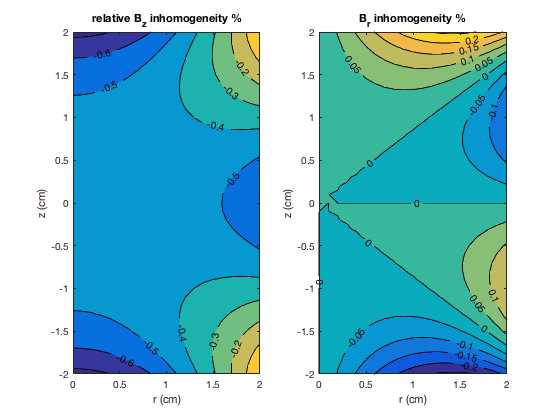


subplot(1, 2, 1)
contourf(r*100, z*100, (bz-max(bz(:)))/max(bz(:))*100, 'ShowText', 'on')
xlabel('r (cm)');ylabel('z (cm)');
title('relative B_z inhomogeneity %');
subplot(1, 2, 2)
contourf(r*100, z*100, br/max(bz(:))*100, 'ShowText', 'on')
xlabel('r (cm)');ylabel('z (cm)');
title('B_r inhomogeneity %');

## Field inhomogeneity (R=7.9 cm, Z-axis)

Consider a Helmholtz coil with `R=7.7 cm`, and `N=117`. For a given current `I=1 A`, the field is

R=0.079; I0=1.0; nTurn=117;
[r, z] = meshgrid(0:0.001:0.020, -0.020:0.001:0.020);
[br, bz]=Condition.coil_field_Helmholtz(r, z, R, I0, nTurn);
fprintf('max Bz = %8.6f Tesla\n', max(bz(:)))

max Bz = 0.001341 Tesla


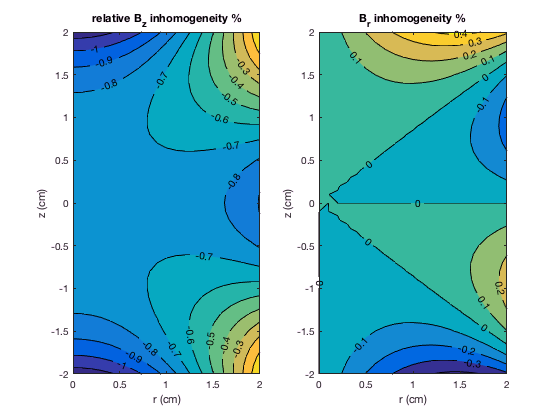


subplot(1, 2, 1)
contourf(r*100, z*100, (bz-max(bz(:)))/max(bz(:))*100, -0.1:0.01:0, 'ShowText', 'on')
xlabel('r (cm)');ylabel('z (cm)');
title('relative B_z inhomogeneity %');
subplot(1, 2, 2)
contourf(r*100, z*100, br/max(bz(:))*100, 'ShowText', 'on')
xlabel('r (cm)');ylabel('z (cm)');
title('B_r inhomogeneity %');

## Field inhomogeneity (R=6.8 cm, X-axis)

Consider a Helmholtz coil with `R=6.7 cm`, and `N=100`. For a given current `I=1 A`, the field is

R=0.068; I0=1.0; nTurn=100;
[r, z] = meshgrid(0:0.001:0.020, -0.020:0.001:0.020);
[br, bz]=Condition.coil_field_Helmholtz(r, z, R, I0, nTurn);
fprintf('max Bz = %8.6f Tesla\n', max(bz(:)))

max Bz = 0.001339 Tesla


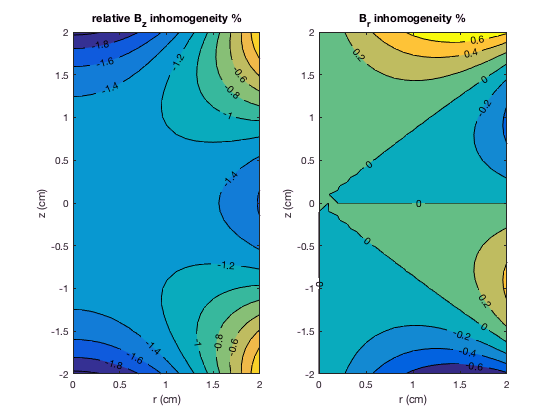


subplot(1, 2, 1)
contourf(r*100, z*100, (bz-max(bz(:)))/max(bz(:))*100, 'ShowText', 'on')
xlabel('r (cm)');ylabel('z (cm)');
title('relative B_z inhomogeneity %');
subplot(1, 2, 2)
contourf(r*100, z*100, br/max(bz(:))*100, 'ShowText', 'on')
xlabel('r (cm)');ylabel('z (cm)');
title('B_r inhomogeneity %');